syms s t

$$y = 1-{\mathrm{e}}^{-t}$$

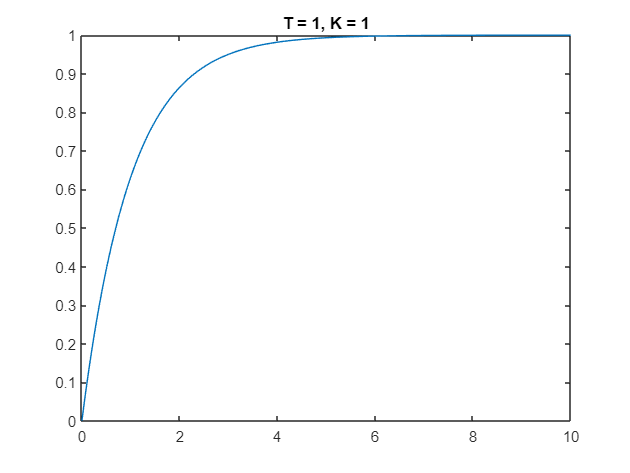

$$y = 2-2\,{\mathrm{e}}^{-t}$$

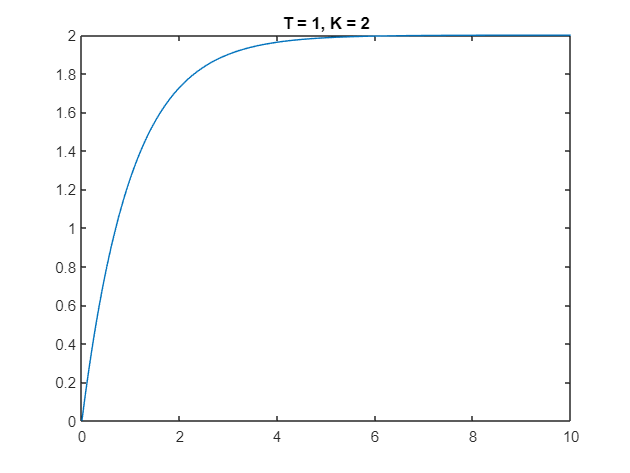

% A)
tt = 0:0.05:60;
K1= [1,2];
T= 1;
for K = K1
    G= K/(T*s+1);
    y = ilaplace(G/s, s , t)
    y_num = double(subs(y, t, tt));
    figure;
    plot(tt,y_num);
    title("T = " + T + ", K = " + K);
    xlim([0 10]);
end

$$y = 1-{\mathrm{e}}^{-10\,t}$$

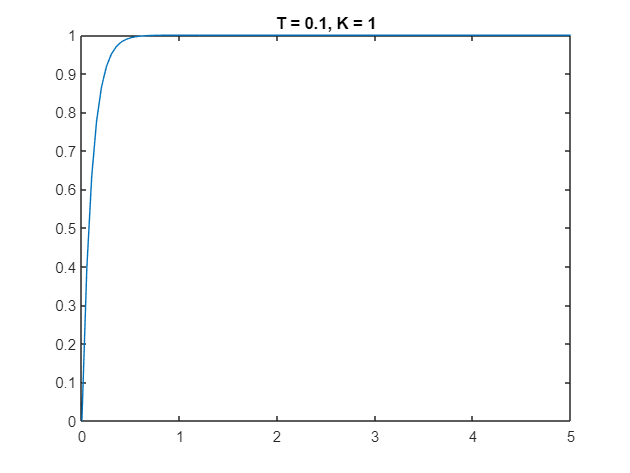

$$y = 10-10\,{\mathrm{e}}^{-10\,t}$$

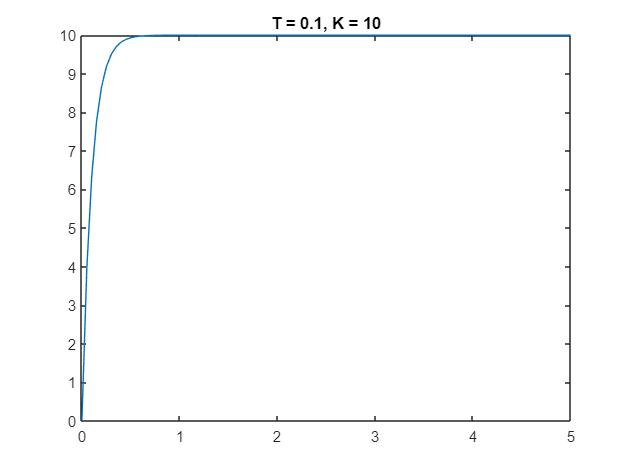

K1= [1,10];
T= 0.1;
for K = K1
    G= K/(T*s+1);
    y = ilaplace(G/s, s , t)
    y_num = double(subs(y, t, tt));
    figure;
    plot(tt,y_num);
    xlim([0 5]);
    title("T = " + T + ", K = " + K);
end

$$y = \frac{1}{10}-\frac{{\mathrm{e}}^{-\frac{t}{10}}}{10}$$

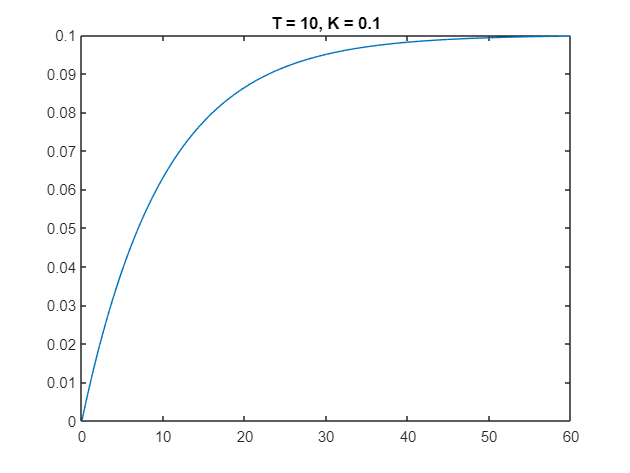

$$y = 1-{\mathrm{e}}^{-\frac{t}{10}}$$

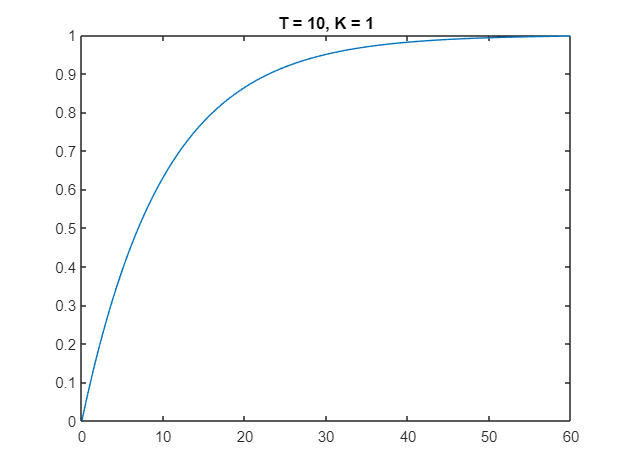

K1= [0.1,1];
T= 10;
for K = K1
    G= K/(T*s+1);
    y = ilaplace(G/s, s , t)
    y_num = double(subs(y, t, tt));
    figure;
    plot(tt,y_num);
    title("T = " + T + ", K = " + K);
end

% B)
G2=1/((s+1)*(s+0.9));
y = ilaplace(G2/s, s , t)

$$y = 10\,{\mathrm{e}}^{-t}-\frac{100\,{\mathrm{e}}^{-\frac{9\,t}{10}}}{9}+\frac{10}{9}$$

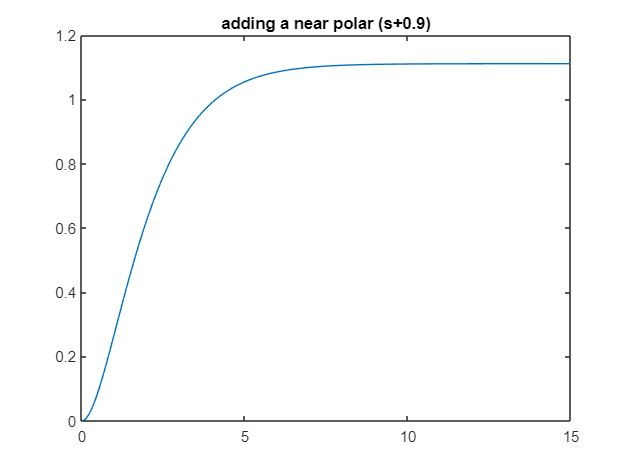

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 15]);
title("adding a near polar (s+0.9)");


G2=1/((s+1)*(s+10));
y = ilaplace(G2/s, s , t)

$$y = \frac{{\mathrm{e}}^{-10\,t}}{90}-\frac{{\mathrm{e}}^{-t}}{9}+\frac{1}{10}$$

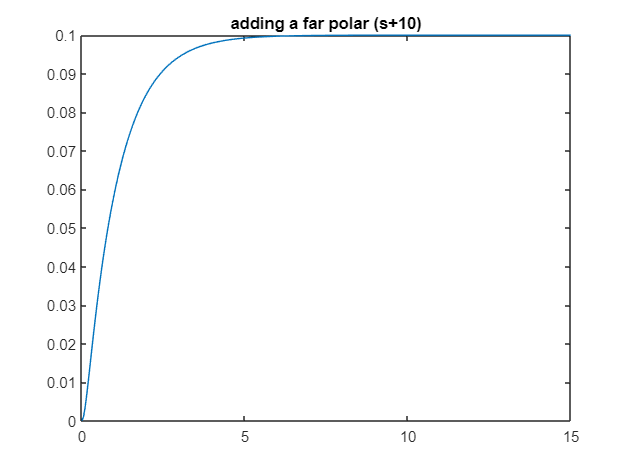

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 15]);
title("adding a far polar (s+10)");

% C-1
K = 1;
T = 1;
G = K/(T*(s+1));
G3 = G*((1/0.9)*s+1);
y = ilaplace(G/s, s , t)

$$y = 1-{\mathrm{e}}^{-t}$$

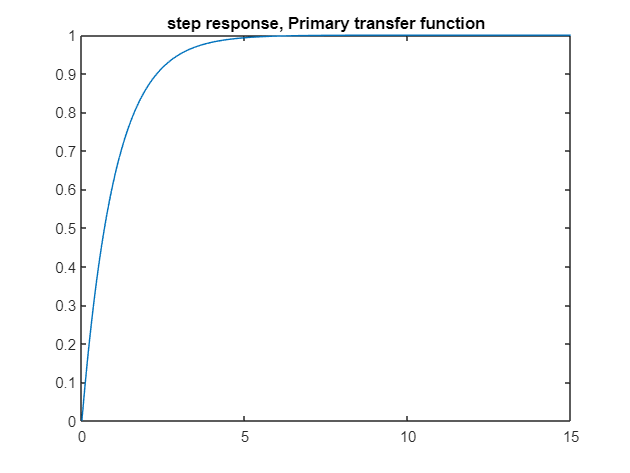

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 15]);
title("step response, Primary transfer function");

y = ilaplace(G3/s, s , t)

$$y = \frac{{\mathrm{e}}^{-t}}{9}+1$$

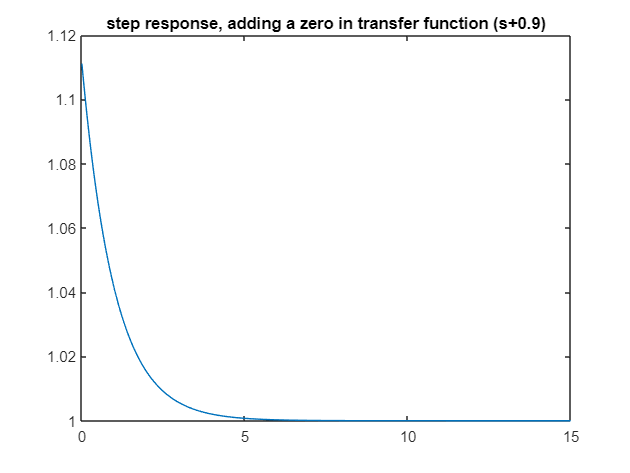

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 15]);
title("step response, adding a zero in transfer function (s+0.9)");

y = ilaplace(G, s , t)

$$y = {\mathrm{e}}^{-t}$$

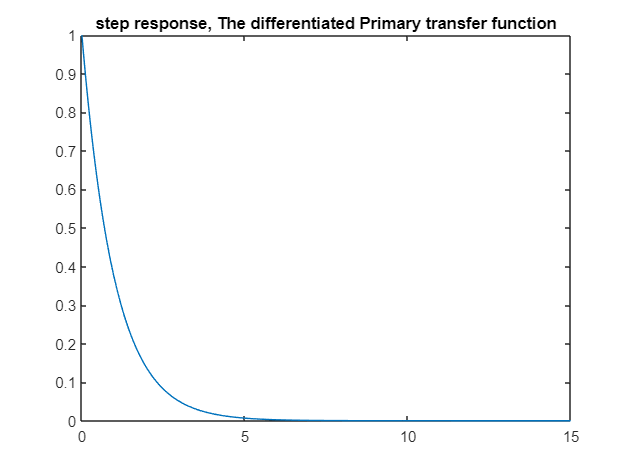

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 15]);
title("step response, The differentiated Primary transfer function");

%C-2
G4 = (1/11)*G*(s+11);
y = ilaplace(G4/s, s , t)

$$y = 1-\frac{10\,{\mathrm{e}}^{-t}}{11}$$

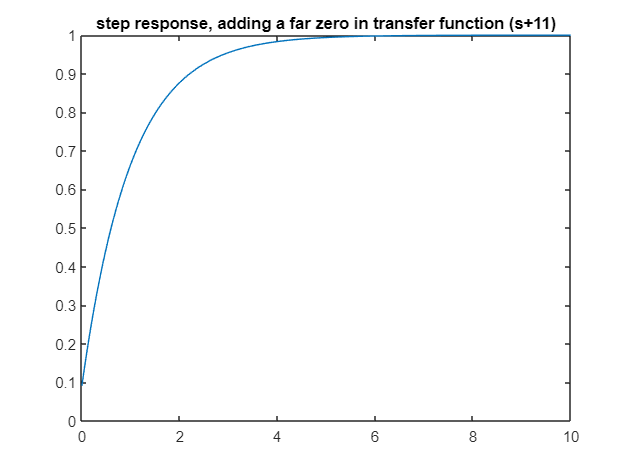

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 10]);
title("step response, adding a far zero in transfer function (s+11)");

G5 = (1/0.05)*G*(s+0.05);
y = ilaplace(G5/s, s , t)

$$y = 19\,{\mathrm{e}}^{-t}+1$$

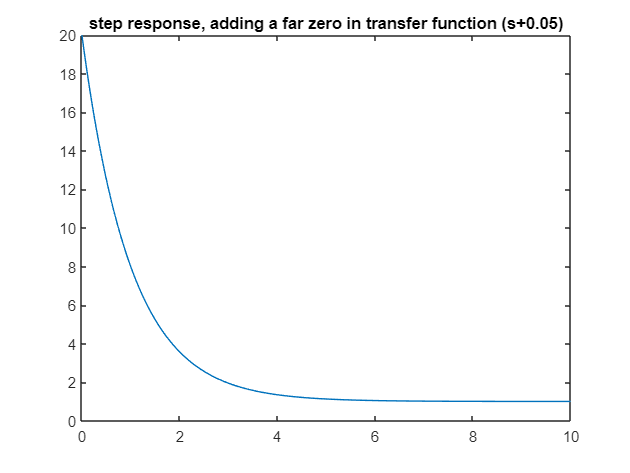

y_num = double(subs(y, t, tt));
figure;
plot(tt,y_num);
xlim([0 10]);
title("step response, adding a far zero in transfer function (s+0.05)");